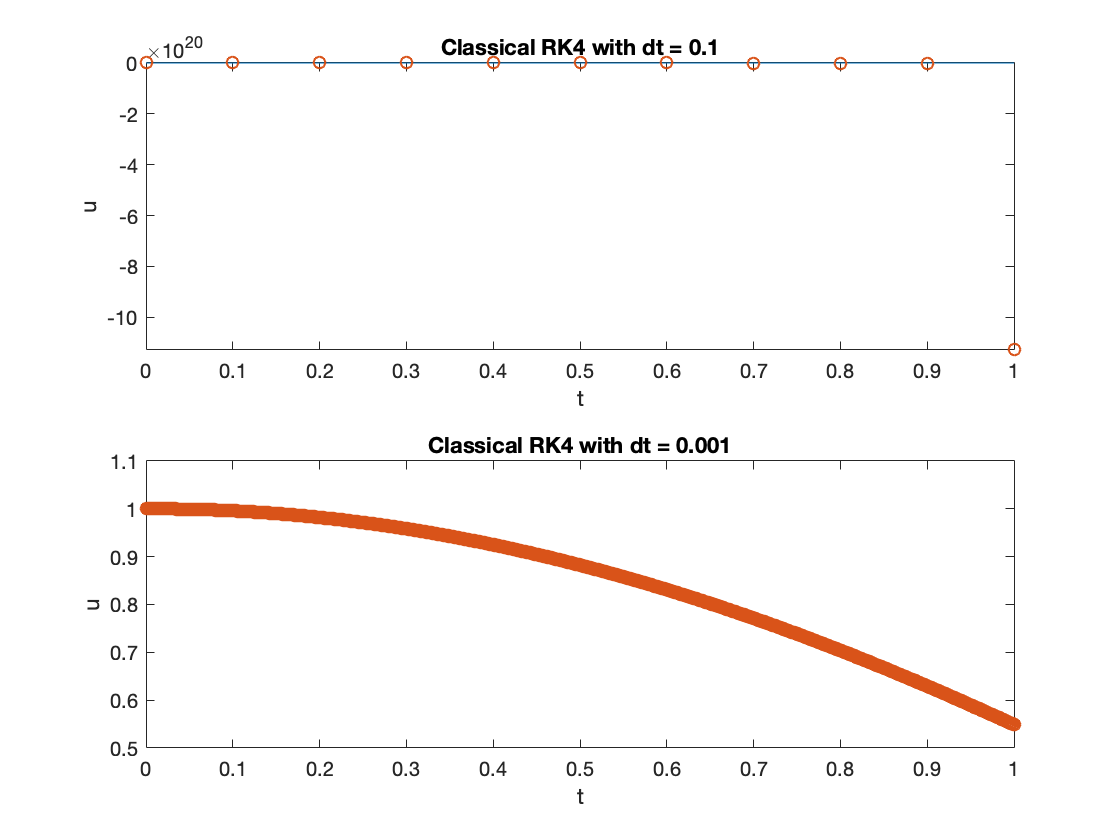

% Problem 4：
% Use Classical RK4 and Euler backwards to solve the ode with dt = 0.1 and 0.001
T = 1;
f = @(u,t) -100*(u-cos(t));
[t,u_exact] = ode45(@(t,u) -100*(u-cos(t)),[0 1], 1); % ode45 gives the exact solution
DT = [0.1,0.001];
% Classical Runge-Kutta 4:
hold off;
figure(1)
for i=1:2
    dt = DT(i);
    x = 0:dt:T;
    u = zeros(1,length(x));
    u(1)=1;
    for j = 1:(length(x)-1)
        tn = x(j);
        Y1 = u(j);
        Y2 = Y1 + dt/2*f(Y1,tn);
        Y3 = Y1 + dt/2*f(Y2,tn+dt/2);
        Y4 = Y1 + dt*f(Y3,tn+dt/2);
    
        u(j+1) = u(j) + dt/6*(f(Y1,tn)+2*f(Y2,tn+dt/2)+2*f(Y3,tn+dt/2)+...
            f(Y4,tn+dt));
    end
    subplot(2,1,i)
    
    plot(t,u_exact);
    title("Classical RK4 with dt = "+num2str(dt))
    hold on;
    scatter(x,u);
    xlabel("t")
    ylabel("u")
end
hold off;

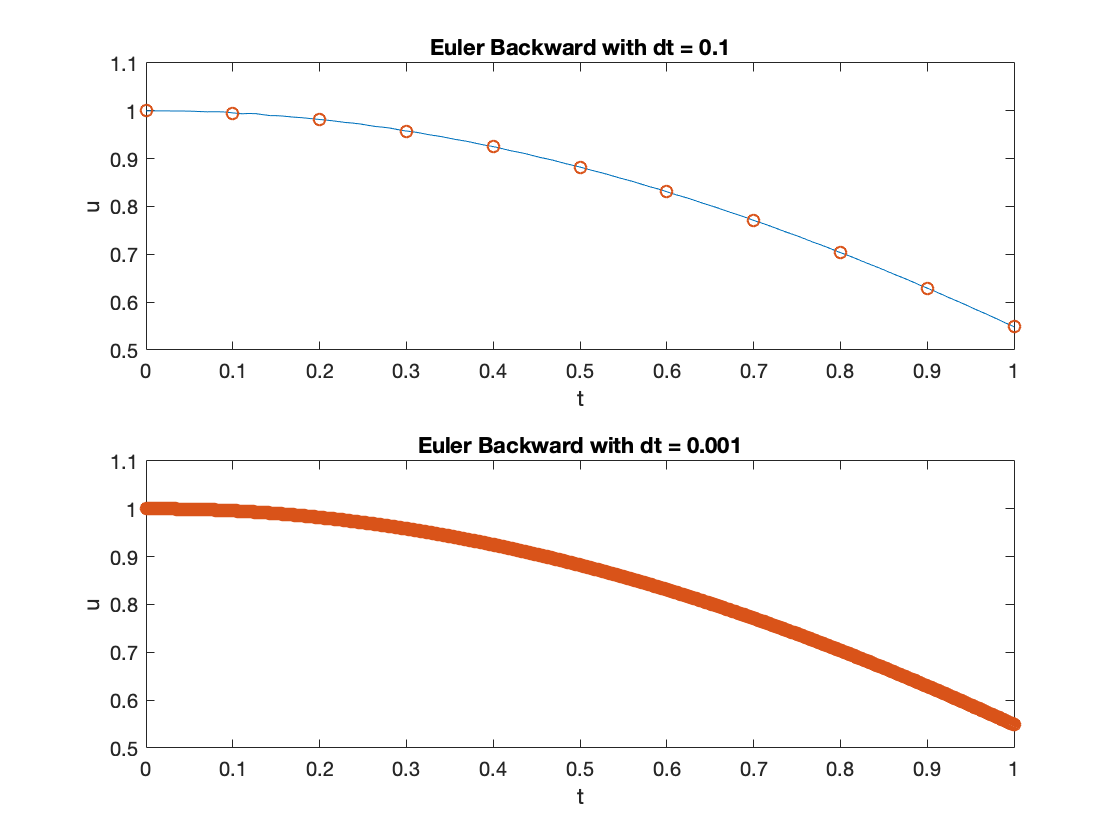

%%
% Euler Backward
figure(2)
for i = 1:2
    dt = DT(i);
    x = 0:dt:T;
    u = zeros(1,length(x));
    u(1)=1;
    for j = 1:(length(x)-1)
        u(j+1)= (u(j)+ 100*cos(x(j)+dt)*dt)/(100*dt+1); % The work for this is on next page
    end
    subplot(2,1,i)
    plot(t,u_exact);
    hold on;
    title("Euler Backward with dt = "+num2str(dt))
    xlabel("t")
    ylabel("u")
    scatter(x,u);
end
hold off;